# A GC-MS Method for Analysis of Hydrodistillied Fraser Fir Oil

**Al Fischer  **

January 31, 2019

## Introduction

*Abies fraseri* is a coniferous tree endemic to the Southern Appalachian Mountains of Virginia, North Carolina, and Tennessee. It is widely known and cultivated as a Christmas tree, but has come under threat due to the invasive balsam woolly adelgid.  Although, previous studies have looked into the chemosystematics of fir trees using solid-phase micro extraction (SPME) with GC-MS [1, 2], the goal of this study is to determine how SPME results may differ from traditional oil extraction by hydro-distillation. This initial experiment will focus on developing a GC-MS analysis method.  I hypothesize that SPME provides a better picture of more the volatile components of *A. fraseri *extract, while hydro-distillation will provide a more complete extraction of higher boiling boint compounds.  Hydrodistillation will be conducted on fir needles and the hydrophobic extract will be analyzed by gas chromatography-mass spectrometry (GC-MS).  Again, during this initial study, the goal will be to develop a GC-MS method with adequate resolution to identify all components present and to begin to identify the primary constituents using mass spectrometry.

## Materials and Methods

### Sample Preparation

Fir oil was extracted using steam distillation, with a homemade distillation apparatus.  It consisted of an 1-L Erlenmeyer flask, a heat source (hotplate), a glass angle adapter with a neoprene stopper on one end to fit into the flask and a ground-glass fitting on the other side to mate to a standard jacketed cold water condenser.  The distillate was collected into a graduated cylinder.

Prior to the steps listed below, fir branches were cut from the bottom 0.5 m of farmed Fraser fir trees.  Cut branches were placed in a polyethylene bag and transported to the lab in a cooler on ice for further processing.

**Steps**:

- Fraser fir (*Abies fraseri*) needles and branch tips were stripped from the branches by hand and chopped with stainless steel shears.

- 0.532 kg of the cut needles and branch tips was added to an Erlenmeyer flask.

- 300 mL of tap water was added to the flask.

- The distillation apparatus was placed on the flask and the mixture was heated to a boil on a hotplate.

- Approximately 50 mL of distillate was collected into a 50-ml graduated cylinder.

- The distillate was allowed to sit for an hour to give the organic layer time to fully separate from the aqueous layer.

- The upper organic layer was removed with a glass pipette and placed in a glass amber 1-dram vial for analysis; the aqueous layer was mixed 50:50 with isopropyl alcohol and placed under refridgeration at 5°C for preservation.

**Total yield of oil: 1.487 mL**

### **GC-MS Analysis**

- 1 drop of the oil was placed in amber glass vial and diluted to 2 ml with ethanol.

- The sample was run on an Agilent 5890 gas chromatograph equipped with an Agilent 5975C Mass-seletive Detector; the GC and MS parameters can be found in the tables below.

- Data were acquired with the Agilent GC-MS data acquisition software; chromatograms and mass spectra were exported as CSV files and processed in Julia.

% GC Parameter Table
Parameter = ["Make & Model"; "Column"; "Carrier"; "Injection Port Temp (°C)"; "Initial Oven Temp"; "Oven Ramp Rate"; "Final Oven Temp"];
Value = ["Agilent 5890"; "HP-5ms"; "UCG He @ 9 psi"; "250"; "30°C for 1 min"; "30°C per min"; "250°C for 3 min"];
t = table(Parameter, Value);
t.Parameter = categorical(t.Parameter);
t.Value = categorical(t.Value);
disp(t)

           Parameter                 Value     
    ________________________    _______________

    Make & Model                Agilent 5890   
    Column                      HP-5ms         
    Carrier                     UCG He @ 9 psi 
    Injection Port Temp (°C)    250            
    Initial Oven Temp           30°C for 1 min 
    Oven Ramp Rate              30°C per min   
    Final Oven Temp             250°C for 3 min



% MS Parameter Table
Parameter = ["Make & Model"; "Column"; "Carrier"; "Injection Port Temp (°C)"; "Initial Oven Temp"; "Oven Ramp Rate"; "Final Oven Temp"];
Value = ["Agilent 5890"; "HP-5ms"; "UCG He @ 9 psi"; "250"; "30°C for 1 min"; "30°C per min"; "250°C for 3 min"];
t = table(Parameter, Value);
t.Parameter = categorical(t.Parameter);
t.Value = categorical(t.Value);
disp(t)

           Parameter                 Value     
    ________________________    _______________

    Make & Model                Agilent 5890   
    Column                      HP-5ms         
    Carrier                     UCG He @ 9 psi 
    Injection Port Temp (°C)    250            
    Initial Oven Temp           30°C for 1 min 
    Oven Ramp Rate              30°C per min   
    Final Oven Temp             250°C for 3 min



## Results and Data Analysis

### Chromatogram: First Glance

%% Setup the Import Options
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [5, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Time", "Counts", "VarName3"];
opts.VariableTypes = ["double", "double", "string"];
opts = setvaropts(opts, 3, "WhitespaceRule", "preserve");
opts = setvaropts(opts, 3, "EmptyFieldRule", "auto");
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tic = readtable("20180831_abiesFraseri_tic01.txt", opts);
clear opts


**Plot the Data:**

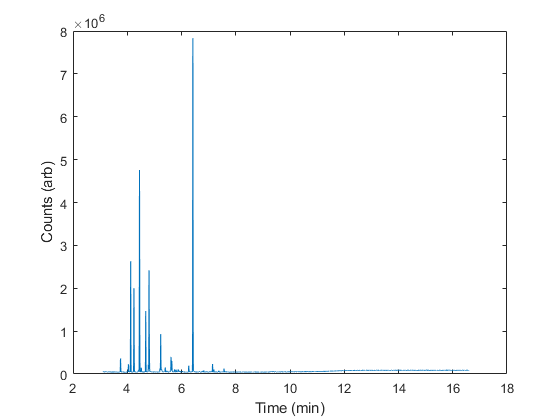

plot(tic.Time, tic.Counts)
xlabel('Time (min)')
ylabel('Counts (arb)')

There are several options for the molecular ion (A).  The ion at 136 seems to be a good candiate.  Assuming a molecule composed of C and H, this would give C$_{10}$H$_{16}$.  This fits quite well with the isotopic abudances given in Table 2.2 of McLafferty [3].  This formula should yield A = 100%, A+1 = 11%, and A+2 = 0.5%, very close to the 100, 10.8, and 0.49% abundances observed for the sample.  This formula would fit for the compound suspected, $\alpha$-pinene.

$\alpha$-pinene has a unique, multi-ringed structure (Figure 5).  We see several routes toward losing a methyl group (CH$_3$, m/z = 15), and indeed there is a sizable peak at 136 - 15 = 121 (Figure 3). Another likely fragmenation would be to break of a portion of the 4-memebered ring, losing two methyl groups and a C atom (total m/z = 42).  This would yield a mass of 94, which is present in small amounts; however, a mass of 94 could easily rearrage to lose a proton and produce the base peak of m/z = 93.  Overall, the mass spectrum supports the hypothesis that peak represents $\alpha$-pinene.

## Conclusions

The hydrodistillation of fraser fir needles successfully produced aThe hydrodistillation of fraser fir needles successfully produced a reasonable yield of oil. In all, 1.487 mL of oil was obtained from approximately 0.5 kg of needles. Although obtaining this amount of oil was very labor intensive with the small-scale glassware, the process could be easily scaled up to achieve the same amount of oil in less time and with less labor.

The GC-MS method developed here provided adequate resolution to identify the major components of the extract. Twelve major peaks were observed, all of which were well-resolved. One peak was identified as α-pinene, and the remaining peaks will be identified in future analysis. Overall, the method presented here is suitable for additional analyses exploring the difference between hydrodistilled extracts and SPME extracts and no changes will be made to the method moving forward. reasonable yield of oil. In all, 1.487 mL of oil was obtained from approximately 0.5 kg of needles. Although obtaining this amount of oil was very labor intensive with the small-scale glassware, the process could be easily scaled up to achieve the same amount of oil in less time and with less labor.

The GC-MS method developed here provided adequate resolution to identify the major components of the extract. Twelve major peaks were observed, all of which were well-resolved. One peak was identified as α-pinene, and the remaining peaks will be identified in future analysis. Overall, the method presented here is suitable for additional analyses exploring the difference between hydrodistilled extracts and SPME extracts and no changes will be made to the method moving forward.

## References